# Basketball Players

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads, formats, and normalizes the data.

data = readtable("./data/bball.csv");
data.pos = categorical(data.pos);
stats = data{:, [5 6 11:end]};
labels = data.Properties.VariableNames([5 6 11:end]);
statsNorm = normalize(stats);

This code groups the data using a Gaussian mixture model.

gmModel = fitgmdist(statsNorm, 2, "Replicates", 5, "RegularizationValue", 0.02);

grp = cluster(gmModel, statsNorm);

## Task 1

The table `data` contains statistics for several basketball players. The players' positions are contained in `data.pos`.

The numeric statistics have been extracted and normalized in `statsNorm`, then used in a Gaussian mixture model (GMM) to divide the players into two groups in `grp`.

ct = crosstab(data.pos, grp)

ct =    115     4
    42     2
   206   110
   111     7
     0     2
    11    38
     1   366
    10    89


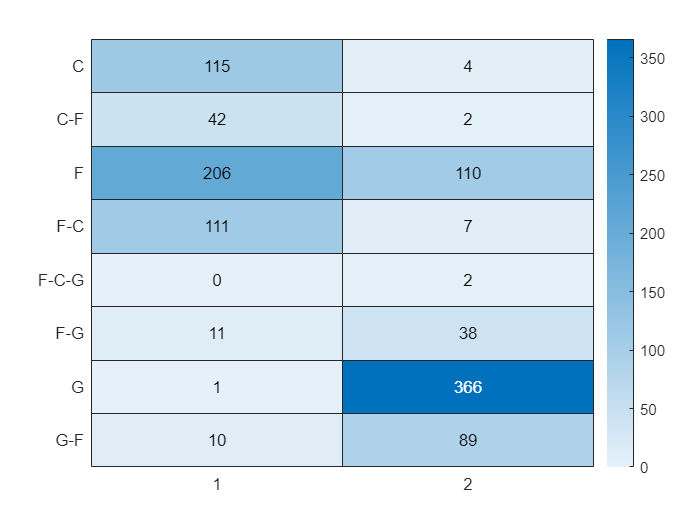

heatmap(ct,"YDisplayLabels", categories(data.pos))

## Task 2

The Gaussian mixture model `gmModel` contains information about the underlying Gaussian distributions used to create the clusters. For example, you can extract the means of the distributions, which correspond to the centroids of the clusters.

`centroids` `=` `model``.mu`

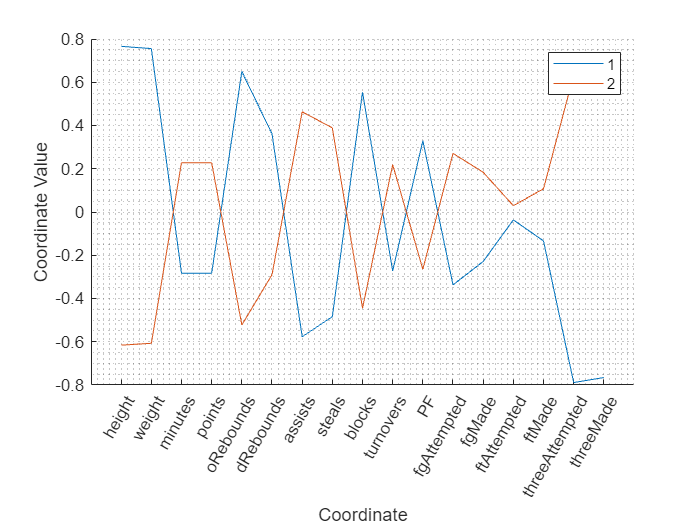

parallelcoords(gmModel.mu, "Group", 1:2)
grid minor
xticklabels(labels)
xtickangle(60)

## Task 3

cev = evalclusters(statsNorm, "gmdistribution", "DaviesBouldin", "KList", 2:4)

cev =   DaviesBouldinEvaluation with properties:

    NumObservations: 1117
         InspectedK: [2 3 4]
    CriterionValues: [1.0052 1.4500 1.6328]
           OptimalK: 2


optK = cev.OptimalK

optK = 2